# Use CNN to achieve character recognition

## 1. Training Data Preparations

clc
clear

dataset_folder = 'dataset';
imds = imageDatastore(dataset_folder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Split train set and validation set
[imdsTrain, imdsValidaiton] = splitEachLabel(imds, 0.75, 'randomized');

ans =      1     1


## 2. Define the structure of CNN

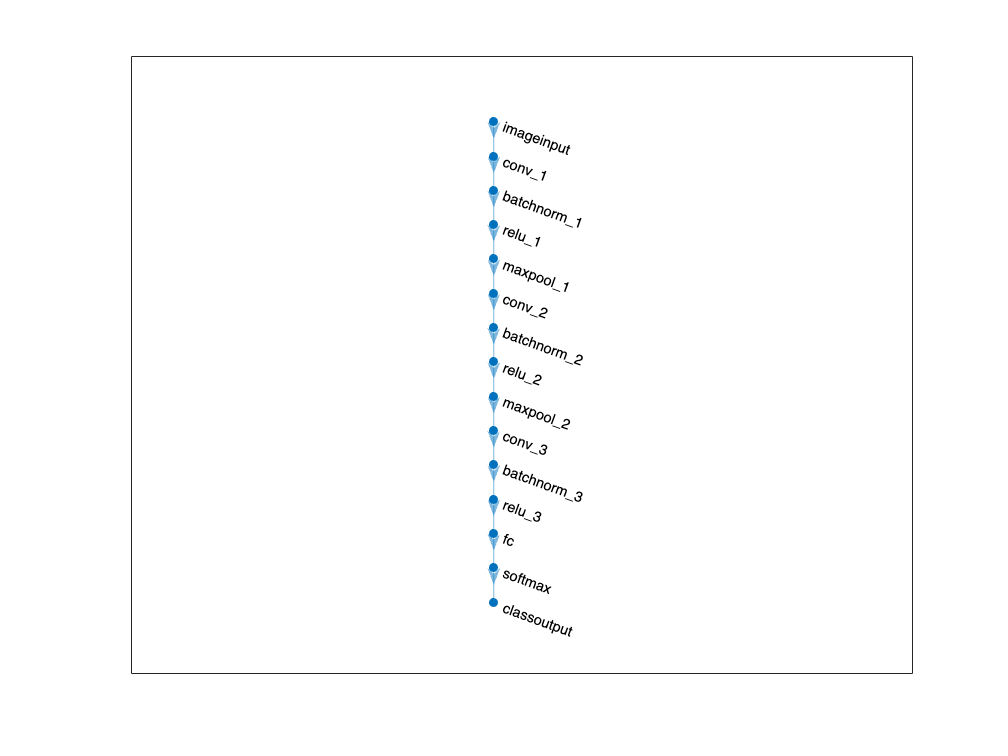

% Structure of CNN
layers = [
    imageInputLayer([128 128 1])
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer];

lgraph = layerGraph(layers);
clf
plot(lgraph);

% Training Option
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress');

## 3. Train the network

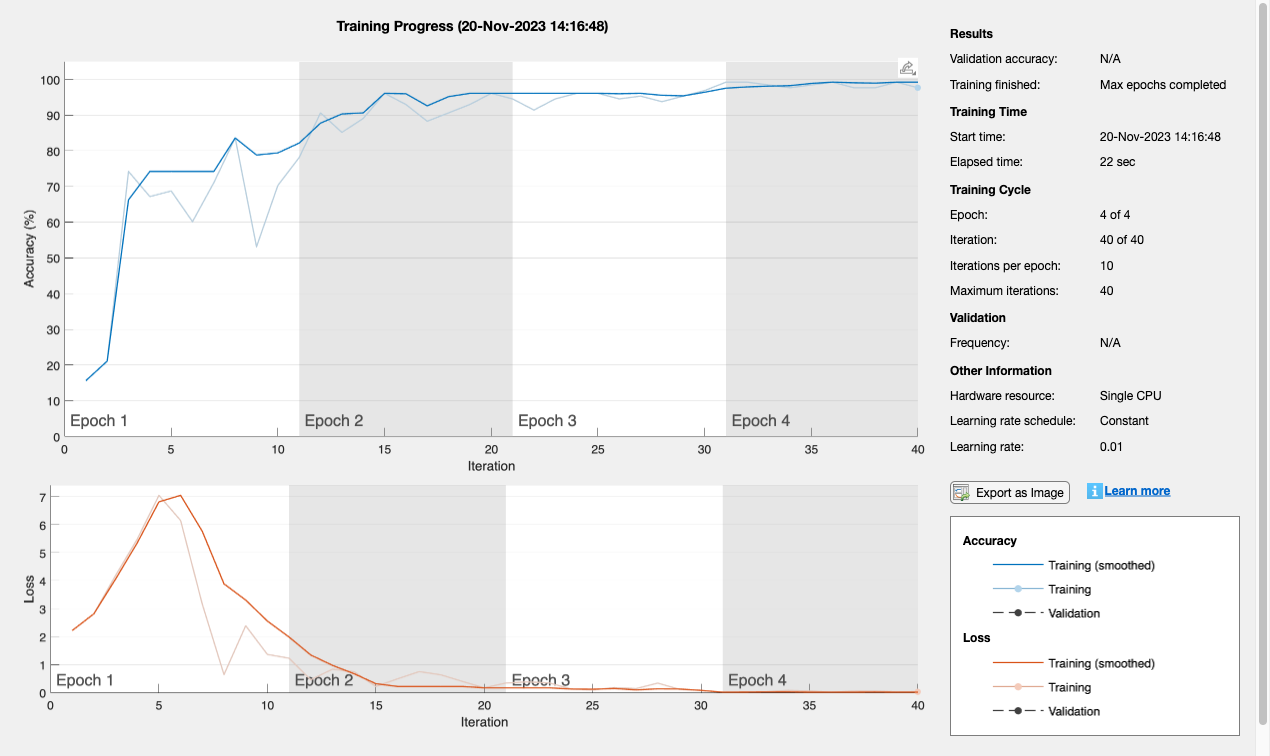

net = trainNetwork(imdsTrain,layers,options);

save('CNN_Small.mat', "net");

## 4. Calculate Accuracy

### 4.1 Accuracy on validation set

load('CNN_Small.mat')

YPred = classify(net,imdsValidaiton);
accuracy = sum(YPred == imdsValidaiton.Labels)/numel(imdsValidaiton.Labels);
disp(accuracy)

    0.9615



### 4.2 Accuracy on test set

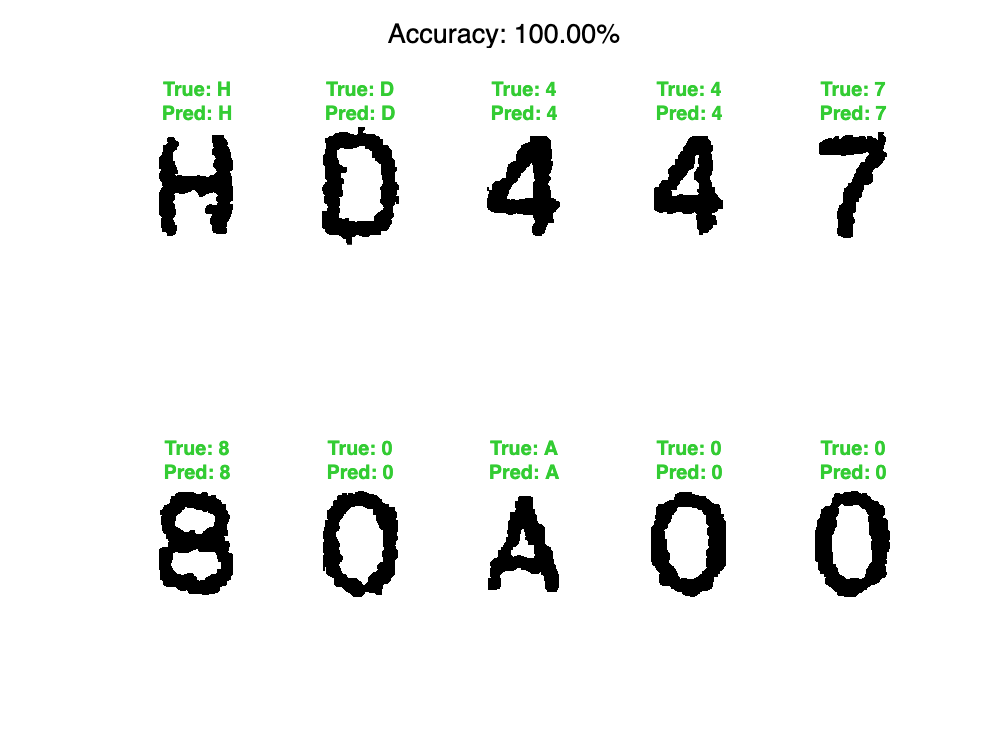

character_folder = 'character';
imdsTest = imageDatastore(character_folder, 'IncludeSubfolders', true);
imdsTest.Labels = categorical(["H","D","4","4","7","8","0","A","0","0"]);

test_pred = classify(net,imdsTest);
test_accuracy = sum(test_pred == imdsTest.Labels)/numel(imdsTest.Labels);

clf
for i = 1:10
    I = readimage(imdsTest, i);
    True_Label = imdsTest.Labels(i);
    Pred_Label = test_pred(i);
    subplot(2, 5, i);
    imshow(I);
    if True_Label == Pred_Label
        color = [0.2 0.8 0.2];
    else
        color = [1 0 0];
    end
    title({['True: ' char(True_Label)], ['Pred: ' char(Pred_Label)]},'FontSize', 11,'Color', color);
end
sgtitle(sprintf('Accuracy: %.2f%%',100*test_accuracy));